# PRACTICA 10: Respuesta en frecuencia

## **INTRODUCCIÓN**

**Resumen de sección 4.10-Lathi**

### **Diseño de filtros por colocación de polos y ceros de H(s)**

#### Dependencia de la respuesta en frecuencia de los polos y ceros de H(s)

La respuesta de frecuencia de un sistema es básicamente la información sobre la capacidad de filtrado del sistema. Una función de transferencia del sistema se puede expresar como:

donde $z_1$, $z_2$, ... , $z_N$ son $\lambda_1$, $\lambda_2$, ... , $\lambda_N$ son los polos de *H(s)*. Ahora el valor de la función de transferencia *H(s)* para alguna frecuencia s = p es:

Esta ecuación consta de factores de la forma p−$z_i$ y p−$\lambda_i$. El factor p−$z_i$ es un número complejo representado por un vector dibujado desde el punto z hasta el punto p en el plano complejo, como se ilustra en la imagen. La longitud de este segmento de línea es |p − $z_i$|, la magnitud de p − $z_i$. El ángulo de este segmento de línea dirigido (con el eje horizontal) es $\angle$(p − $z_i$). Para calcular H(s) en s = p, trazamos segmentos de recta desde todos los polos y ceros de H(s) hasta el punto p, como se muestra en la imagen. El vector que conecta un cero zi con el punto p es p − $z_i$. Sea la longitud de este vector ri y su ángulo con el eje horizontal sea $\varphi_i$. Entonces p−$z_i$ =  ${r_i e}^{j\varphi_i }$ . De manera similar, el vector que conecta un polo λi con el punto p es p − $\lambda_i$ =  ${d_i e}^{j\varphi_i }$ , donde di y θi son la longitud y el ángulo (con el eje horizontal)

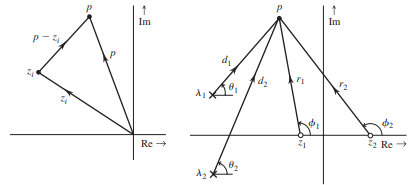

#### Filtros de paso bajo 

Un filtro de paso bajo típico tiene una ganancia máxima en ω = 0. Debido a que un polo mejora la ganancia en las frecuencias cercanas, necesitamos colocar un polo (o polos) en el eje real opuesto al origen ( jω = 0). La función de transferencia de este sistema es:

Si d es la distancia desde el polo −ωc hasta un punto jω (figura 4.50a), entonces:

Con H(0) = 1. A medida que ω aumenta, d aumenta y |H(jω)| disminuye monótonamente con ω, como se ilustra en la figura 4.50d con la etiqueta N = 1. Este es claramente un filtro de paso bajo con ganancia mejorada en las proximidades de ω = 0. 

#### Filtros prácticos y sus especificaciones

La vida real no permite tal visión del mundo. Las cosas tienen que ser grises o tonos de gris. En la práctica, podemos realizar una variedad de características de filtro que solo pueden acercarse a las características ideales. 

Un filtro ideal tiene una banda de paso (ganancia unitaria) y una banda de parada (ganancia cero) con una transición repentina de la banda de paso a la banda de parada. No hay banda de transición. Por otra parte, para filtros prácticos (o realizables), la transición de la banda de paso a la banda de supresión (o viceversa) es gradual y tiene lugar en una banda finita de frecuencias. Además, para filtros realizables, la ganancia no puede ser cero en una banda finita (condición de Paley-Wiener). Como resultado, no puede haber una verdadera banda de parada para filtros prácticos. Por lo tanto, definimos una banda de parada como una banda sobre la cual la ganancia está por debajo de un pequeño número G. De este modo:

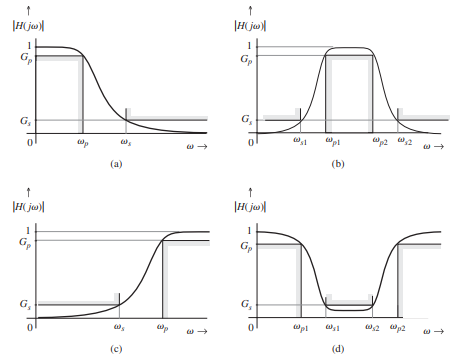

- **Tenemos e l siguiente circuto:**

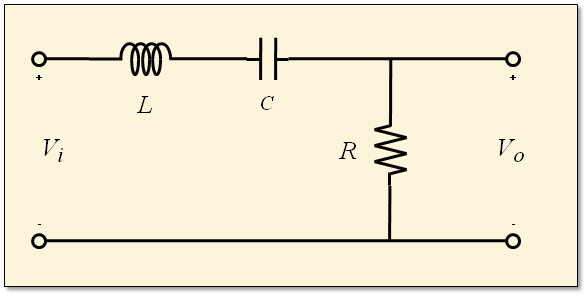

**El modelado de este circuito es el siguiente:**

syms V0(t) Vi(t) t R L C s
assume(Vi(t), 'real');
eqn = L*diff(V0, t, 2) + R*diff(V0,t) + (1/(C))*V0 == R*diff(Vi,t)

$$eqn(t) = R\,\frac{\partial }{\partial t}V_{0}\left(t\right)+L\,\frac{\partial^{2}}{\partial t^{2}}V_{0}\left(t\right)+\frac{V_{0}\left(t\right)}{C}=R\,\frac{\partial }{\partial t}\mathrm{Vi}\left(t\right)$$

Vi2=dsolve(eqn,V0)

Vi2 = struct with fields:
    Vi: C1
    V0: 0


`El voltaje suministrado es igual a voltaje consumido`

**Para hallar la funcion de transferencia debemos depejar tanto a Vo (Voltaje de salida), y Vi (voltaje de entrada) tenemos lo siguiente**

V0*(s^2+(R/L)*s+(1/L*C))==Vi*(R*s)

$$ans(t) = V_{0}\left(t\right)\,\left(\frac{C}{L}+s^{2}+\frac{R\,s}{L}\right)=R\,s\,\mathrm{Vi}\left(t\right)$$

H(s)=V0/Vi

$$H(s) = \frac{V_{0}\left(t\right)}{\mathrm{Vi}\left(t\right)}$$

H(s)=(R*s)/(s^2+(R/L)*s+(1/L*C)) %Función de Transferencia

$$H(s) = \frac{R\,s}{\frac{C}{L}+s^{2}+\frac{R\,s}{L}}$$

**Calculamos la respuesta al impulso del sistema:**

L=1; C=510*10^-9; R=50; Vi=heaviside(t);
eqn1 = L*diff(V0, t, 2) + R*diff(V0,t) + (1/(C))*V0 == R*diff(Vi,t)

$$eqn1(t) = \frac{\partial^{2}}{\partial t^{2}}V_{0}\left(t\right)+50\,\frac{\partial }{\partial t}V_{0}\left(t\right)+\frac{8421504501960785\,V_{0}\left(t\right)}{4294967296}=50\,\delta (t)$$

V=dsolve(eqn1)

$$V = C_{1}\,{\mathrm{e}}^{-25\,t}\,\cos\left(\frac{\sqrt{8418820147400785}\,t}{65536}\right)-C_{2}\,{\mathrm{e}}^{-25\,t}\,\sin\left(\frac{\sqrt{8418820147400785}\,t}{65536}\right)+\frac{327680\,\sqrt{5}\,\sqrt{1683764029480157}\,{\mathrm{e}}^{-25\,t}\,\mathrm{sign}\left(t\right)\,\sin\left(\frac{\sqrt{8418820147400785}\,t}{65536}\right)}{1683764029480157}$$

**Definimos la variable omega que representa la frecuencia de señales sinusoidales:**

omega = 1/(sqrt((L*C)))

omega = 1.4003e+03


Va=cos(1/2*omega*t);
Vb=sin(1/2*omega*t);
Vc=cos(1*omega*t);
Vd=sin(1*omega*t);
Ve=cos(2*omega*t);
Vf=sin(2*omega*t);
eqna = L*diff(V0, t, 2) + R*diff(V0,t) + (1/(C))*V0 == R*diff(Va,t)

$$eqna(t) = \frac{\partial^{2}}{\partial t^{2}}V_{0}\left(t\right)+50\,\frac{\partial }{\partial t}V_{0}\left(t\right)+\frac{8421504501960785\,V_{0}\left(t\right)}{4294967296}=-\frac{38490605863298775\,\sin\left(\frac{1539624234531951\,t}{2199023255552}\right)}{1099511627776}$$

eqnb = L*diff(V0, t, 2) + R*diff(V0,t) + (1/(C))*V0 == R*diff(Vb,t)

$$eqnb(t) = \frac{\partial^{2}}{\partial t^{2}}V_{0}\left(t\right)+50\,\frac{\partial }{\partial t}V_{0}\left(t\right)+\frac{8421504501960785\,V_{0}\left(t\right)}{4294967296}=\frac{38490605863298775\,\cos\left(\frac{1539624234531951\,t}{2199023255552}\right)}{1099511627776}$$

eqnc = L*diff(V0, t, 2) + R*diff(V0,t) + (1/(C))*V0 == R*diff(Vc,t)

$$eqnc(t) = \frac{\partial^{2}}{\partial t^{2}}V_{0}\left(t\right)+50\,\frac{\partial }{\partial t}V_{0}\left(t\right)+\frac{8421504501960785\,V_{0}\left(t\right)}{4294967296}=-\frac{38490605863298775\,\sin\left(\frac{1539624234531951\,t}{1099511627776}\right)}{549755813888}$$

eqnd = L*diff(V0, t, 2) + R*diff(V0,t) + (1/(C))*V0 == R*diff(Vd,t)

$$eqnd(t) = \frac{\partial^{2}}{\partial t^{2}}V_{0}\left(t\right)+50\,\frac{\partial }{\partial t}V_{0}\left(t\right)+\frac{8421504501960785\,V_{0}\left(t\right)}{4294967296}=\frac{38490605863298775\,\cos\left(\frac{1539624234531951\,t}{1099511627776}\right)}{549755813888}$$

eqne = L*diff(V0, t, 2) + R*diff(V0,t) + (1/(C))*V0 == R*diff(Ve,t)

$$eqne(t) = \frac{\partial^{2}}{\partial t^{2}}V_{0}\left(t\right)+50\,\frac{\partial }{\partial t}V_{0}\left(t\right)+\frac{8421504501960785\,V_{0}\left(t\right)}{4294967296}=-\frac{38490605863298775\,\sin\left(\frac{1539624234531951\,t}{549755813888}\right)}{274877906944}$$

eqnf = L*diff(V0, t, 2) + R*diff(V0,t) + (1/(C))*V0 == R*diff(Vf,t)

$$eqnf(t) = \frac{\partial^{2}}{\partial t^{2}}V_{0}\left(t\right)+50\,\frac{\partial }{\partial t}V_{0}\left(t\right)+\frac{8421504501960785\,V_{0}\left(t\right)}{4294967296}=\frac{38490605863298775\,\cos\left(\frac{1539624234531951\,t}{549755813888}\right)}{274877906944}$$